clear; close all; clc; rng shuffle;

normZero = @(x) x-max(x(:));
rf2Bmode = @(x) 20*log10(abs(hilbert(x)));

%%
elem_pitch = 0.30e-3;

pml_x_size = 2*40;                % [grid points]
pml_y_size = 2*14;                % [grid points]

% set total number of grid points not including the PML
Nx = 2*600 - 2 * pml_x_size;      % [grid points]
Ny = 2*540 - 2 * pml_y_size;      % [grid points]
% Ny = Ny/2;

PML_size = [pml_x_size pml_y_size];       % size of the PML in grid points TONY

ratio = 8;
dy = elem_pitch/ratio;          % grid point spacing in the y direction [m]
dx = dy;

kgrid = kWaveGrid(Nx, dx, Ny, dy)

kgrid =   kWaveGrid with properties:

                   Nx: 1040
                   Ny: 1024
                   Nz: 0
                   dx: 3.7500e-05
                   dy: 3.7500e-05
                   dz: 0
               kx_vec: [1040×1 double]
               ky_vec: [1024×1 double]
               kz_vec: 0
                    k: [1040×1024 double]
               kx_max: 8.3776e+04
               ky_max: 8.3776e+04
               kz_max: 0
                k_max: 8.3776e+04
                  dim: 2
           nonuniform: 0
                   dt: 'auto'
                   Nt: 'auto'
                x_vec: [1040×1 double]
                y_vec: [1024×1 double]
                z_vec: 0
                    x: [1040×1024 double]
                    y: [1040×1024 double]
                    z: 0
                   kx: [1040×1024 double]
                   ky: [1040×1024 double]
                   kz: 0
               x_si


Nx_tot = Nx;
Ny_tot = Ny;
rx = ones(Nx_tot,1)*linspace(-Ny_tot*dy/2,Ny_tot*dy/2,Ny_tot);
rz = linspace(0,Nx_tot*dx,Nx)'*ones(1,Ny_tot);

c0 = 1540;
t_end = (Nx*dx)*2/c0;     % [s]
kgrid.makeTime(c0, [], t_end);
fs = 1/kgrid.dt;

nLines = floor(Ny/ratio) % vary slightly plm_y to get nLines=

nLines = 128

axAxis = 0:(kgrid.Nt-1); axAxis = axAxis*1/fs*c0/2;
latAxis = 0:(nLines-1);
latAxis = latAxis-mean(latAxis);
latAxis = latAxis*elem_pitch;

z = axAxis; %(100:end);
x = latAxis;

focal_distance = 20e-3;

x(end)*2

ans = 0.0735

z(end)

ans = 0.0354

sos_mean = 1540;
sos_std = 0;

alpha_mean = randi([8 36],1,2)/20 %[0.4 1.8];

alpha_mean =     1.3500    1.6500


alpha_std = [0 0];

rho_mean = randi([18 25],1,2)*100/2 %[1000 1000 1000 1000 1000];

rho_mean =         1150        1050


rho_std = randi([2 10],1,2)/200 %[0.01 0.06];

rho_std =     0.0150    0.0500



offset = 5;

% 30 variable rho
% 30 variable att
% 30 variable rho att

radius = (randi([6 10])/10)*(randi([16 24],1,2)/20)*1e-2/dx % [0.6-1.2]*[80% 120%]

radius =   192.0000  181.3333


center = [randi([0 38])/10 randi([16 24])/10]*1e-2/dx + [0 offset]%

center =   533.3333  458.3333


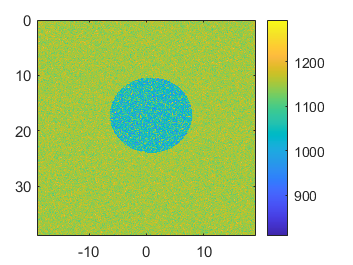


[xGrid, yGrid] = meshgrid(1:Ny, 1:Nx);

distFromCenter = sqrt((xGrid - center(1)).^2 / radius(1)^2 + (yGrid - center(2)).^2 / radius(2)^2);
circleMatrix = double(distFromCenter <= 1);

% 
% figure;
% imagesc(x*1e2, z*1e2, circleMatrix)

% SoS
medium.sound_speed = patterns(sos_mean, sos_std, 'homo', [], Nx, Ny);

% Density
density_mean = zeros(size(circleMatrix));
density_mean(circleMatrix == 0) = rho_mean(1);
density_mean(circleMatrix == 1) = rho_mean(2);

density_std = zeros(size(circleMatrix));
density_std(circleMatrix == 0) = rho_std(1);
density_std(circleMatrix == 1) = rho_std(2);

medium.density = patterns(density_mean, density_std, 'homo', [], Nx, Ny);


figure
imagesc(x*1e3,z*1e3,medium.density); colorbar;

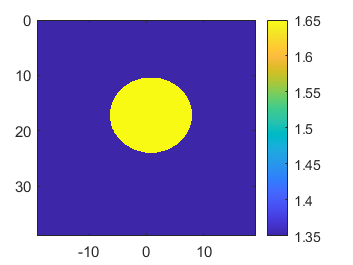


% Attenuation
alpha_coeff_mean = zeros(size(circleMatrix));
alpha_coeff_mean(circleMatrix == 0) = alpha_mean(1);
alpha_coeff_mean(circleMatrix == 1) = alpha_mean(2);

alpha_coeff_std = zeros(size(circleMatrix));
alpha_coeff_std(circleMatrix == 0) = alpha_std(1);
alpha_coeff_std(circleMatrix == 1) = alpha_std(2);

medium.alpha_coeff = patterns(alpha_coeff_mean, alpha_coeff_std, 'homo', [], Nx, Ny);

figure
imagesc(x*1e3,z*1e3, alpha_coeff_mean); colorbar;


medium.alpha_power = 1;
medium.alpha_mode = 'no_dispersion';

folder_path = 'simulations\';

% Get a list of all files and folders in this folder
files = dir(folder_path);

fileNames = string({files.name})';
fileNames = fileNames(contains(fileNames, 'Batch'))


fileNames = 

  0×0 empty string array



fileNames_set = cell(size(fileNames));

for i = 1:length(fileNames)
    temp = dir(folder_path+fileNames(i));
    temp = string({temp.name})';
    temp = temp(contains(temp, "rf"));
    fileNames_set{i} = temp;
end

data = struct with fields:
    alpha_coeff_mean: [1040×1024 double]
     alpha_coeff_std: [1040×1024 double]
        density_mean: [1040×1024 double]
         density_std: [1040×1024 double]
                  fs: 1.3689e+08
              medium: [1×1 struct]
                  rf: [6835×128 double]
                   x: [-0.0190 -0.0187 -0.0184 -0.0181 -0.0178 -0.0175 -0.0172 -0.0169 -0.0166 -0.0163 -0.0160 -0.0158 -0.0154 -0.0151 -0.0148 -0.0145 -0.0142 -0.0139 -0.0136 -0.0133 -0.0130 -0.0127 -0.0124 -0.0121 -0.0118 -0.0115 -0.0112 -0.0109 … ]
                   z: [5.5687e-04 5.6250e-04 5.6812e-04 5.7375e-04 5.7937e-04 5.8500e-04 5.9063e-04 5.9625e-04 6.0187e-04 6.0750e-04 6.1312e-04 6.1875e-04 6.2437e-04 6.3000e-04 6.3563e-04 6.4125e-04 6.4687e-04 6.5250e-04 6.5812e-04 6.6375e-04 … ]


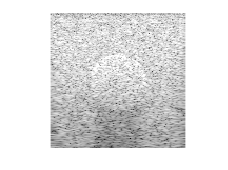

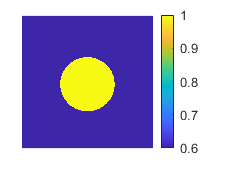

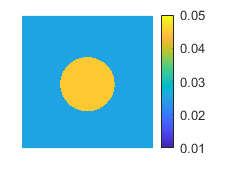

for i = 5%1:length(fileNames)
    for j = 8%1:length(fileNames_set{i})
        data = load(folder_path+fileNames(i)+"\"+fileNames_set{i}(j))
        figure;
        imagesc(data.x*1e2, data.z*1e2, rf2Bmode(data.rf),[-90 -30]);
        colormap gray; axis image; axis off;%colorbar
        figure;
        imagesc(data.x*1e2, data.z*1e2, data.medium.alpha_coeff);
        axis image; axis off; colorbar;
        figure;
        imagesc(data.x*1e2, data.z*1e2, data.density_std, [0.01 0.05]);
        axis image; axis off; colorbar;
    end
end

## In vivo

addpath(genpath('mpUS_Verasonics\'))
%% IDs
control_id = [547, 550, 1, 2, 3, 4, 670, 671];
diet_id = [545, 546, 548, 549, 5, 6, 7, 8, 672, 673, 674, 675];
rats_IDs = [control_id, diet_id];

%% Settings
fs = 25e6;

selected_fr = 1;
wk = 2;
rat_id = 547; %675;

RFdata_liver = load("mpUS_Verasonics\"+num2str(wk)+"week\"+num2str(rat_id)+"\BRF_"+num2str(rat_id)+".mat"); %564 582 467
sam = RFdata_liver.BRF(:,:,1);

z = linspace(0, 34.9888, size(sam,1))*1e-2;
x = linspace(0, 38.4, size(sam,2))*1e-2;

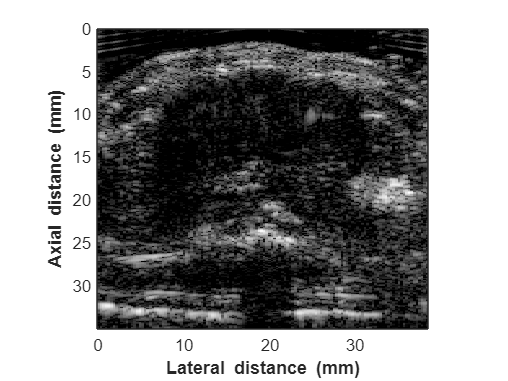

Bmode = db(abs(hilbert(sam)));
Bmode = Bmode - max(Bmode(:));

% Plotting
dynRange = [-40 0];

figure;
% Plot the Bmode image
imagesc(x*1e2, z*1e2, Bmode, dynRange);
colormap(gray); % Set the colormap for the Bmode image
% h = colorbar;
% ylabel(h, 'dB');
axis image; % Maintain the aspect ratio
xlabel('\bfLateral distance (mm)');
ylabel('\bfAxial distance (mm)');

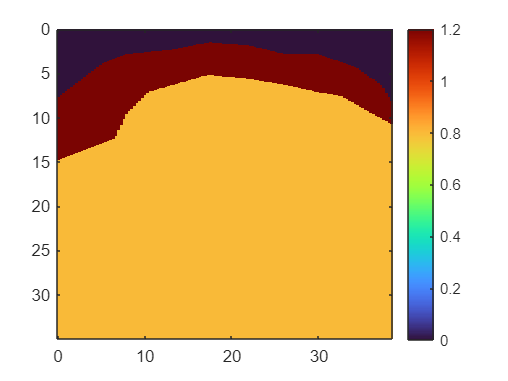

%% Parameters BSC
weeks = [0, 2];
fr = 1;

ACS_map_seg  = load("mpUS_Verasonics\ACS maps\"+...
    "ACS_w"+num2str(weeks(wk))+"_"+num2str(rat_id)+".mat","ACS_map_seg");
ACS_map_seg = ACS_map_seg.ACS_map_seg;

ACS_map = zeros(size(sam,[1,2]));

% Layers ACS
n_lay = 3;
alphaG = 1e-6;                     % Gel [dB/cm/MHz]
alphaM = 1.2;                   % Muscle [dB/cm/MHz]
alphaL = 0.8;   % Liver [dB/cm/MHz]
alpha_layers = [alphaG, alphaM, alphaL];

for i = 1:n_lay
    ACS_map(ACS_map_seg==i) = alpha_layers(i);    
end

figure;
imagesc(x*1e2, z*1e2, ACS_map, [0 1.2]); colorbar;colormap turbo;

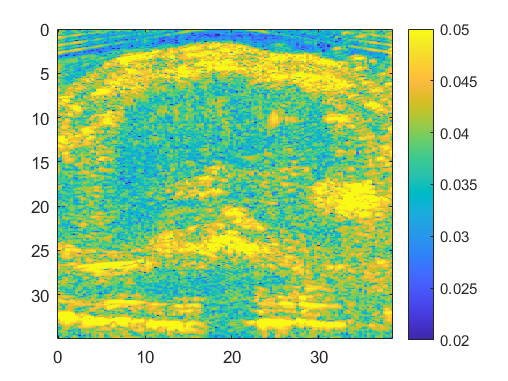



figure;
imagesc(x*1e2, z*1e2, rescale(Bmode, 0.01, 0.06), [0.02 0.05]); colorbar;

%%
elem_pitch = 0.30e-3;

pml_x_size = 2*40;                % [grid points]
pml_y_size = 2*14;                % [grid points]

% set total number of grid points not including the PML
Nx = 2*546 - 2 * pml_x_size;      % [grid points]
Ny = 2*540 - 2 * pml_y_size;      % [grid points]
% Ny = Ny/2;

PML_size = [pml_x_size pml_y_size];       % size of the PML in grid points TONY

ratio = 8;
dy = elem_pitch/ratio;          % grid point spacing in the y direction [m]
dx = dy;

kgrid = kWaveGrid(Nx, dx, Ny, dy)

kgrid =   kWaveGrid with properties:

                   Nx: 932
                   Ny: 1024
                   Nz: 0
                   dx: 3.7500e-05
                   dy: 3.7500e-05
                   dz: 0
               kx_vec: [932×1 double]
               ky_vec: [1024×1 double]
               kz_vec: 0
                    k: [932×1024 double]
               kx_max: 8.3776e+04
               ky_max: 8.3776e+04
               kz_max: 0
                k_max: 8.3776e+04
                  dim: 2
           nonuniform: 0
                   dt: 'auto'
                   Nt: 'auto'
                x_vec: [932×1 double]
                y_vec: [1024×1 double]
                z_vec: 0
                    x: [932×1024 double]
                    y: [932×1024 double]
                    z: 0
                   kx: [932×1024 double]
                   ky: [932×1024 double]
                   kz: 0
               x_size: 0.03


Nx_tot = Nx;
Ny_tot = Ny;
rx = ones(Nx_tot,1)*linspace(-Ny_tot*dy/2,Ny_tot*dy/2,Ny_tot);
rz = linspace(0,Nx_tot*dx,Nx)'*ones(1,Ny_tot);

rx(end)*2

ans = 0.0384

rz(end)

ans = 0.0349


c0 = 1540;
t_end = (Nx*dx)*2/c0;     % [s]
kgrid.makeTime(c0, [], t_end);

fs = 1/kgrid.dt;
fs*1e-6

ans = 136.8889


nLines = floor(Ny/ratio); % vary slightly plm_y to get nLines=
axAxis = 0:(kgrid.Nt-1); axAxis = axAxis*1/fs*c0/2;
latAxis = 0:(nLines-1);
latAxis = latAxis-mean(latAxis);
latAxis = latAxis*elem_pitch;

z = axAxis(100:end)

z =     0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008


x = latAxis

x =    -0.0190   -0.0187   -0.0184   -0.0181   -0.0178   -0.0175   -0.0172   -0.0169   -0.0166   -0.0163   -0.0160   -0.0158   -0.0154   -0.0151   -0.0148   -0.0145   -0.0142   -0.0139   -0.0136   -0.0133   -0.0130   -0.0127   -0.0124   -0.0121   -0.0118   -0.0115   -0.0112   -0.0109   -0.0106   -0.0103   -0.0100   -0.0097   -0.0094   -0.0091   -0.0088   -0.0085   -0.0082   -0.0079   -0.0076   -0.0073   -0.0070   -0.0067   -0.0064   -0.0061   -0.0058   -0.0055   -0.0052   -0.0049   -0.0046   -0.0043



focal_distance = 20e-3;

% % Layers SoS
% n_lay = 3;
% alphaG = 1e-6;                     % Gel [dB/cm/MHz]
% alphaM = 1.2;                   % Muscle [dB/cm/MHz]
% alphaL = 0.8;   % Liver [dB/cm/MHz]
% alpha_layers = [alphaG, alphaM, alphaL];
% 
% for i = 1:n_lay
%     ACS_map(ACS_map_seg==i) = alpha_layers(i);    
% end

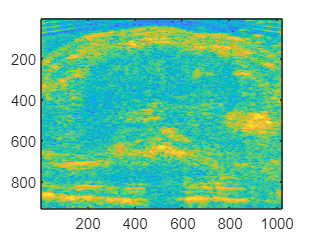

sos_mean = 1540;
sos_std = 0.02;
% SoS
medium.sound_speed = sos_mean + sos_mean.*sos_std.*randn(Nx, Ny);

load("mpUS_Verasonics\Bmode_w2_547.mat")

% Density
density_mean = 1000;
density_std = imresize(rescale(Bmode, 0.01, 0.06), [Nx, Ny],'bicubic');

medium.density = density_mean + density_mean.*density_std.*randn(Nx, Ny);

figure;
imagesc(density_std)

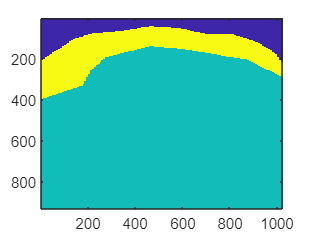


load("mpUS_Verasonics\ACS_map_seg_w2_547.mat")

% Layers ACS
n_lay = 3;
alphaG = 1e-6;                     % Gel [dB/cm/MHz]
alphaM = 1.2;                   % Muscle [dB/cm/MHz]
alphaL = 0.6;   % Liver [dB/cm/MHz]
alpha_layers = [alphaG, alphaM, alphaL];
ACS_map = zeros(size(Bmode,[1,2]));
for i = 1:n_lay
    ACS_map(ACS_map_seg==i) = alpha_layers(i);    
end

% Attenuation
alpha_coeff_mean = imresize(ACS_map, [Nx, Ny],'nearest');
alpha_coeff_std = 0;

medium.alpha_coeff = alpha_coeff_mean + alpha_coeff_mean.*alpha_coeff_std.*randn(Nx, Ny);
figure;
imagesc(medium.alpha_coeff)

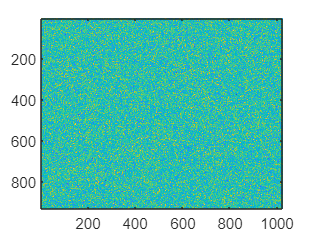




figure;
imagesc(medium.sound_speed)

function [med, med_mean, med_std] = patterns(var_mean, var_std, patt_type,var_params, Nx, Ny)
    switch patt_type
        case 'homo'
            med_mean = var_mean;
            med_std = var_std;
        case 'circle'
            circle_ind = boolean(makeDisc(Nx, Ny,...
                round(var_params.center_depth/var_params.dx)+var_params.offset, Ny/2, ...
                round(var_params.radius_disk/var_params.dx)));
            med_mean = var_mean(1)*(~circle_ind) + var_mean(2)*(circle_ind);
            med_std = var_std(1)*(~circle_ind) + var_std(2)*(circle_ind);
        case 'layers_vert'
            layer_pos = var_params.layer_pos/var_params.dx;
            [X,~] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(X<layer_pos) ...
                + var_mean(2)*(X>=layer_pos);
            med_std = var_std(1)*(X<layer_pos) ...
                + var_std(2)*(X>=layer_pos);
        case 'layers_horz'
            layer_pos = var_params.layer_pos/var_params.dy;
            [~,Y] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(Y<layer_pos) ...
                + var_mean(2)*(Y>=layer_pos);
            
            med_std = var_std(1)*(Y<layer_pos) ...
                + var_std(2)*(Y>=layer_pos);
        case 'layers_vert3'
            layer_pos = var_params.layer_pos/var_params.dx;
            [X,~] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(X<layer_pos(1)) ...
                + var_mean(2)*((X<layer_pos(2))&(X>=layer_pos(1)))...
                + var_mean(3)*(X>=layer_pos(2));
            med_std = var_std(1)*(X<layer_pos(1)) ...
                + var_std(2)*((X<layer_pos(2))&(X>=layer_pos(1)))...
                + var_std(3)*(X>=layer_pos(2));
        case 'layers_horz3'
            layer_pos = var_params.layer_pos/var_params.dy;
            [~,Y] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(Y<layer_pos(1)) ...
                + var_mean(2)*((Y<layer_pos(2))&(Y>=layer_pos(1)))...
                + var_mean(3)*(Y>=layer_pos(2));
            med_std = var_std(1)*(Y<layer_pos(1)) ...
                + var_std(2)*((Y<layer_pos(2))&(Y>=layer_pos(1)))...
                + var_std(3)*(Y>=layer_pos(2));
        case 'circleN'
            circle_ind = nan(Nx, Ny, length(var_params.center_depth));
            bg_mask = ones(Nx, Ny);

            med_mean = zeros(Nx, Ny);
            med_std = zeros(Nx, Ny);
            for cc = 1:length(var_params.center_depth)
                circle_ind(:,:,cc) = boolean(makeDisc(Nx, Ny,...
                    round(var_params.center_depth(cc)/var_params.dx)+var_params.offset, var_params.center_lat(cc), ...
                    round(var_params.radius_disk(cc)/var_params.dx)));
                med_mean = med_mean + var_mean(cc)*(circle_ind(:,:,cc));
                med_std = med_std + var_std(cc)*(circle_ind(:,:,cc));
                bg_mask = bg_mask & not(circle_ind(:,:,cc));
            end
            med_mean = med_mean + var_mean(end)*(bg_mask);
            med_std = med_std + var_std(end)*(bg_mask);
        case 'ellipse'
            circle_ind = nan(Nx, Ny, length(var_params.center_depth));
            bg_mask = ones(Nx, Ny);

            med_mean = zeros(Nx, Ny);
            med_std = zeros(Nx, Ny);
            for cc = 1:length(var_params.center_depth)
                circle_ind(:,:,cc) = boolean(makeDisc(Nx, Ny,...
                    round(var_params.center_depth(cc)/var_params.dx)+var_params.offset, var_params.center_lat(cc), ...
                    round(var_params.radius_disk(cc)/var_params.dx)));
                med_mean = med_mean + var_mean(cc)*(circle_ind(:,:,cc));
                med_std = med_std + var_std(cc)*(circle_ind(:,:,cc));
                bg_mask = bg_mask & not(circle_ind(:,:,cc));
            end
            med_mean = med_mean + var_mean(end)*(bg_mask);
            med_std = med_std + var_std(end)*(bg_mask);
        
        otherwise
            med_mean = 0;
            med_std = 0;
            warning('Unexpected type')
    end
    med = med_mean + med_mean.*med_std.*randn(Nx, Ny);
end